clear;
clc;
close all
set(0,'DefaultLineLineWidth', 1.5);
set(0,'defaultAxesFontSize', 14)
set(0,'DefaultFigureWindowStyle', 'docked') 
% set(0,'DefaultFigureWindowStyle', 'normal')
set(0,'defaulttextInterpreter','latex')
rng('default');

## 0. Parametri del reattore

q0 = 10;
V = 150;
k0 = 7.2*10^(10);
ER = 8750;
dHr = -50000;
UA = 50000;
ro = 1000;
Cp = 0.239;
tau_c = 1.5;
CAf = 1;
Tf = 370;

## 1. Equazioni di stato

syms Ca T Tc Tr
syms dCa dT dTc
syms f1(Ca,T,Tc)
syms f2(Ca,T,Tc)
syms f3(Ca,T,Tc)

eq1 = (q0/V)*(CAf - Ca)-k0*exp(-ER/T)*Ca == 0;
eq2 = (q0/V)*(Tf - T) + (((-dHr)*k0)/(ro*Cp))*exp(-ER/T)*Ca + UA/(V*ro*Cp)*(Tc - T) == 0;
eq3 = (Tr - Tc)/tau_c == 0;

f1(Ca,T,Tc) = q0/V*(CAf - Ca)-k0*exp(-ER/T)*Ca;
f2(Ca,T,Tc) = q0/V*(Tf - T) + (((-dHr)*k0)/(ro*Cp))*exp(-ER/T)*Ca + UA/(V*ro*Cp)*(Tc - T);
f3(Ca,T,Tc) = (Tr - Tc)/tau_c;

## 2a. Linearazzazione del sistema

Ca_eq = 0.5054;
T_eq = 315.5491;
Tc_eq = 308;
Tr_eq = 308;

A_c = [-k0*exp(-ER/T_eq) - q0/V, -Ca_eq*ER*k0*exp(-ER/T_eq)/(T_eq^2), 0;
      ((-dHr)*k0/(ro*Cp))*exp(-ER/T_eq), -q0/V + Ca_eq*((-dHr)*k0/(ro*Cp))*exp(-ER/T_eq)*ER/(T_eq^2) - UA/(V*ro*Cp), UA/(V*ro*Cp);
      0, 0, -1/tau_c];
B_c = [0;0;1/tau_c];
C_c = [1, 0, 0];
D_c = 0;

continuous_time_ss = ss(A_c,B_c,C_c,D_c);

## 2b. Discretizzazione del sistema linearizzato

Ts = 1;

discrete_time_ss = c2d(continuous_time_ss, Ts);

A = discrete_time_ss.A;
B = discrete_time_ss.B;
C = discrete_time_ss.C;
D = discrete_time_ss.D;

% Matrice di raggiungibilità
Mr = ctrb(discrete_time_ss);
Mr_rank = rank(Mr);

% Autovalori del sistema
lambda0 = eig(A);

## 3. Vincoli sul sistema linearizzato

Hx = [1,0,0;
      -1,0,0;
      0,1,0;
      0,-1,0;
      0,0,1;
      0,0,-1];
hx = [0.954 - Ca_eq; -0.38 + Ca_eq; 10^6; 10^6; 10^6; 10^6];

Hu = [1;-1];
hu = [310 - Tr_eq; -280 + Tr_eq];

## 4. Invariant set per il sistema controllato

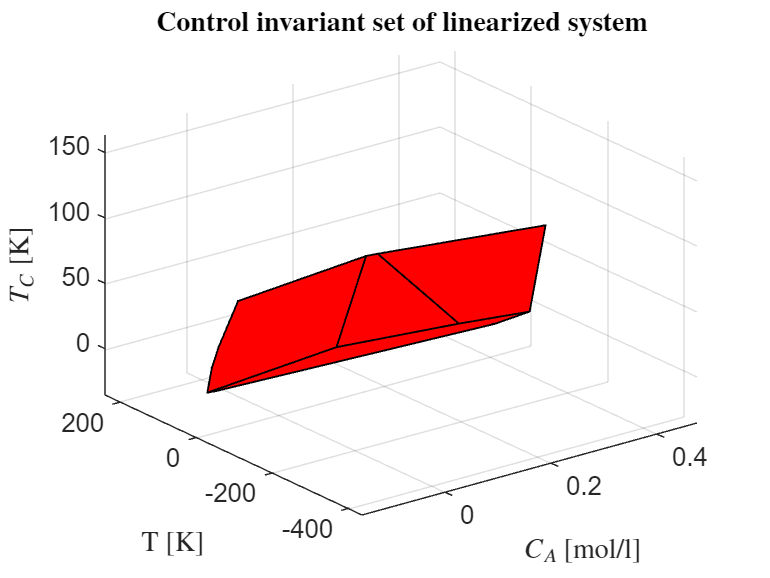

% Matrici del costo quadratico
Q = eye(3);
R = 1;
%   Computazione control invariant set
[CIS_H,CIS_h] = cis(A,B,[0; 0; 0],0,Hx,hx,Hu,hu,Q,R);
CIS = Polyhedron(CIS_H,CIS_h);

figure
CIS.plot();
title('\textbf{Control invariant set of linearized system}');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');

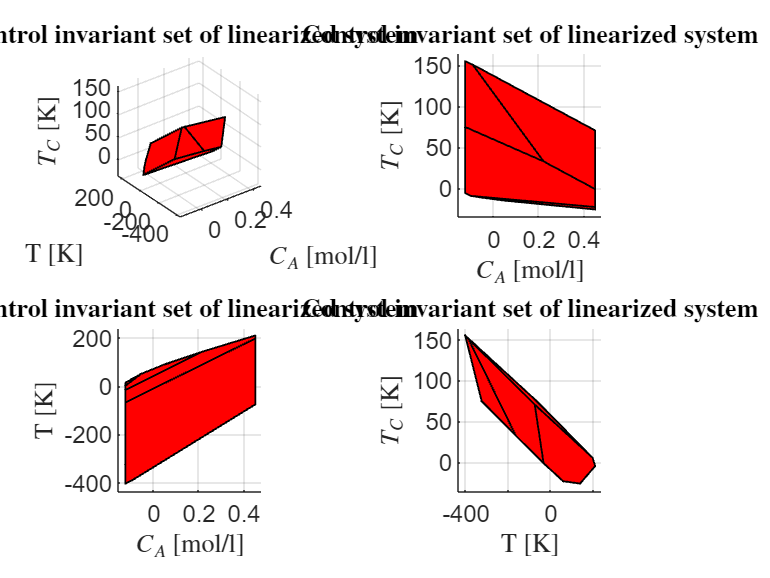

figure
subplot(2,2,1);
CIS.plot();
title('\textbf{Control invariant set of linearized system}');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');

subplot(2,2,2);
CIS.plot();
title('\textbf{Control invariant set of linearized system}');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
view([0 0])

subplot(2,2,3);
CIS.plot();
title('\textbf{Control invariant set of linearized system}');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
view([0 90])

subplot(2,2,4);
CIS.plot();
title('\textbf{Control invariant set of linearized system}');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
view([90 0])

## 5. N-step-controllable set dell'invariant set

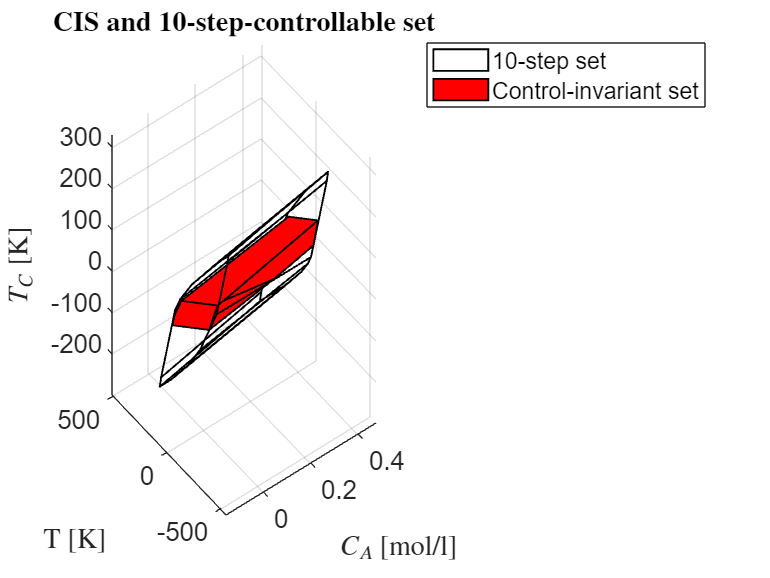

%   Orizzonte di predizione
N = 10;

[Np_steps_H, Np_steps_h] = controllable_set(Hx,hx,Hu,hu,CIS_H,CIS_h,A,B,N);
Np_step_set = Polyhedron('A',Np_steps_H,'b',Np_steps_h);

r_offset = 0.3; % xlim right offset
l_offset = 0.1; % xlim left offset

figure
Np_step_set.plot('Alpha',0);
title('\textbf{CIS and 10-step-controllable set}');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
hold on;
CIS.plot()
legend({'10-step set', 'Control-invariant set'});

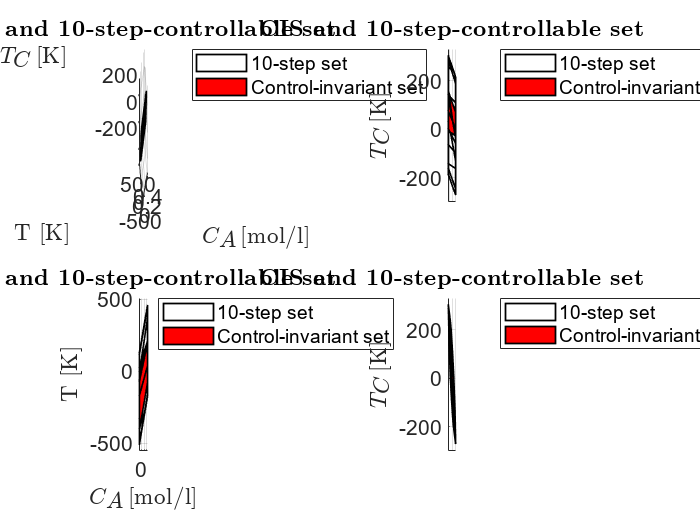


% plot
figure
subplot(2,2,1);
Np_step_set.plot('Alpha',0);
title('\textbf{CIS and 10-step-controllable set}');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
hold on;
CIS.plot()
legend({'10-step set', 'Control-invariant set'});

subplot(2,2,2);
Np_step_set.plot('Alpha',0);
title('\textbf{CIS and 10-step-controllable set}');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
hold on;
CIS.plot()
legend({'10-step set', 'Control-invariant set'});
view([0 0])

subplot(2,2,3);
Np_step_set.plot('Alpha',0);
title('\textbf{CIS and 10-step-controllable set}');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
hold on;
CIS.plot()
legend({'10-step set', 'Control-invariant set'});
view([0 90])

subplot(2,2,4);
Np_step_set.plot('Alpha',0);
title('\textbf{CIS and 10-step-controllable set}');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
hold on;
CIS.plot() 
legend({'10-step set', 'Control-invariant set'});
view([90 0])

## 6. Design MPC e simulazione

%   Numero di step simulati
T_sim = 60;

%   Riferimento
x_ref = [Ca_eq; T_eq; Tc_eq];
u_ref = Tr_eq;

x_ref_lin = [0; 0; 0];
u_ref_lin = 0;

mpc = mpc_ingredients(A,B,Hx,hx,Hu,hu,CIS_H,CIS_h,x_ref_lin,u_ref_lin,Q,R,N);

%   Log stati e ingresso sistema
x_log = zeros(3,T_sim+1);
u_log = zeros(1,T_sim);
flags = zeros(1,T_sim);

x_log(:,1) = [0.853; 296.986; 292];
%x_log(:,1) = [0.853; 270; 280]; Non dovrebbe funzionare con N<=3

for tt = 1:T_sim

    %   Stato sistema linearizzato
    x_lin = x_log(:,tt) - [Ca_eq; T_eq; Tr_eq];
    x_lin_shifted = x_lin - x_ref_lin;

    %   Impostazioni MPC relative alla condizione iniziale
    f = mpc.f_base * x_lin_shifted;
    b_ineq = mpc.b_ineq_base - mpc.b_ineq_x0_factor * x_lin_shifted;
    
    %   Risoluzione problema di ottimizzazione
    [delta_u_seq,~,exitflag] = quadprog(mpc.F,f,mpc.A_ineq,b_ineq);

    flags(tt) = exitflag;

    %   Risposta del sistema
    u_log(tt) = u_ref + delta_u_seq(1);
    
    dxdt = @(t,x) cstr(t,x,u_log(tt),q0,V, k0, ER, dHr, UA, ro, Cp, tau_c, CAf, Tf);
    [~,xx] = ode45(dxdt,[0 Ts],x_log(:,tt));
    x_log(:,tt+1) = xx(end,:)';
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


## 7. Plot dei risultati

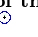

%   Traslazione del CIS e dell'N-step set nelle coordinate originali
CIS_shifted = CIS + x_ref;
Np_step_set_shifted = Np_step_set + x_ref;

figure
Np_step_set_shifted.plot('Alpha',0, 'linestyle', '--', 'linewidth', 0.5);
title('\textbf{Trajectory of the system}');
hold on;
CIS_shifted.plot('Alpha', 0.1);
hold on
plot3(x_log(1,:),x_log(2,:),x_log(3,:),'Color',[0 1 0], 'LineWidth', 3)
scatter3(x_log(1,:),x_log(2,:), x_log(3,:), 50,'blue');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
legend({'10-step set', 'Control-invariant set', 'System''s trajectory', 'Simulation step'})

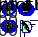



%% plot
figure
subplot(2,2,1)
Np_step_set_shifted.plot('Alpha',0, 'linestyle', '--', 'linewidth', 0.5);
title('\textbf{Trajectory of the system}');
hold on;
CIS_shifted.plot('Alpha', 0.1);
hold on
plot3(x_log(1,:),x_log(2,:),x_log(3,:),'Color',[0 1 0], 'LineWidth', 3)
scatter3(x_log(1,:),x_log(2,:), x_log(3,:), 50,'blue');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
legend({'10-step set', 'Control-invariant set', 'System''s trajectory', 'Simulation step'})

subplot(2,2,2)
Np_step_set_shifted.plot('Alpha',0, 'linestyle', '--', 'linewidth', 0.5);
title('\textbf{Trajectory of the system}');
hold on;
CIS_shifted.plot('Alpha', 0.1);
hold on
plot3(x_log(1,:),x_log(2,:),x_log(3,:),'Color',[0 1 0], 'LineWidth', 3)
scatter3(x_log(1,:),x_log(2,:), x_log(3,:), 50,'blue');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
view([0 0])
legend({'10-step set', 'Control-invariant set', 'System''s trajectory', 'Simulation step'})

subplot(2,2,3)
Np_step_set_shifted.plot('Alpha',0, 'linestyle', '--', 'linewidth', 0.5);
title('\textbf{Trajectory of the system}');
hold on;
CIS_shifted.plot('Alpha', 0.1);
hold on
plot3(x_log(1,:),x_log(2,:),x_log(3,:),'Color',[0 1 0], 'LineWidth', 3)
scatter3(x_log(1,:),x_log(2,:), x_log(3,:), 50,'blue');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
view([0 90])
legend({'10-step set', 'Control-invariant set', 'System''s trajectory', 'Simulation step'})

subplot(2,2,4)
Np_step_set_shifted.plot('Alpha',0, 'linestyle', '--', 'linewidth', 0.5);
title('\textbf{Trajectory of the system}');
hold on;
CIS_shifted.plot('Alpha', 0.1);
hold on
plot3(x_log(1,:),x_log(2,:),x_log(3,:),'Color',[0 1 0], 'LineWidth', 3)
scatter3(x_log(1,:),x_log(2,:), x_log(3,:), 50,'blue');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
view([90 0])
legend({'10-step set', 'Control-invariant set', 'System''s trajectory', 'Simulation step'})